Calcula o calor de vaporização do xileno.

286.4 < T(K) < 616.2

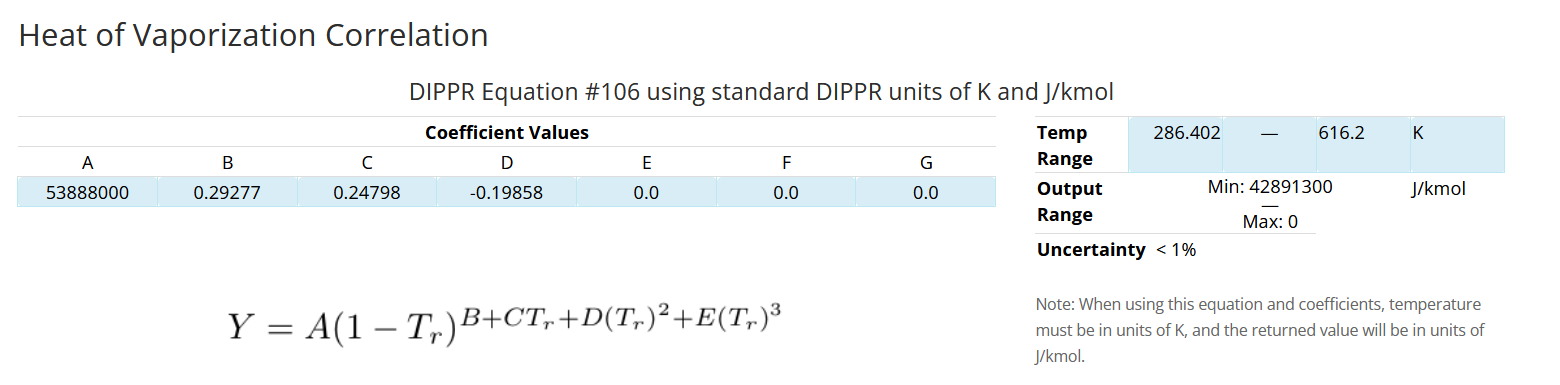

function Y = dH_vap_xil(T_K)


TKmax = 616.2;
TKmin = 286.402;

idxmax = find(T_K >= TKmax);
T_K(idxmax) = TKmax;

idxmin = find(T_K <= TKmin);
T_K(idxmin) = TKmin;

if ~isempty(idxmin)
    warning('A propriedade está a ser extrapolada para baixo!!')
    beep
elseif ~isempty(idxmax)
      warning('A propriedade está a ser extrapolada para cima!!')
      beep
end


Tc = 343.05 + 273.15; % K
T_r = T_K/Tc;
A = 53888000;
B = 0.29277;
C = 0.24798;
D = -0.19858;
E = 0;
Y = A*(1-T_r).^(B + C*T_r + D*T_r.^2 + E*T_r.^3); % J/kmol


Y = Y/1000/1000; % kJ/mol
end